# Synthetic Skin Lesion Image Generation using GANs

In this example, we show how to use MATLAB to generate synthetic images of skin lesions. 

**[Note: The code is adapted with *****very few changes***** from **[**this example**](https://www.mathworks.com/help/deeplearning/ug/train-conditional-generative-adversarial-network.html)**.]**

## Load training data

We use a subset from the ISIC 2016 challenge, Task 3 (*Lesion classification*) data set, consisting of 900 dermoscopic lesion images in JPEG format, distributed in two classes (727 images were labeled as ‘benign’, 173 as ‘malignant’).

% Please adjust the path below, if needed
imageFolder = './ISBI2016_ISIC_Part3_Training_Data';

Create an image datastore containing the images.

datasetFolder = fullfile(imageFolder);

imds = imageDatastore(datasetFolder, ...
    'IncludeSubfolders',true);

Augment the data to include random horizontal flipping and resize the images to have size 64-by-64. 

augmenter = imageDataAugmenter('RandXReflection',true);
augimds = augmentedImageDatastore([64 64],imds,'DataAugmentation',augmenter);    

## Define generator network

filterSize = 5;
numFilters = 64;
numLatentInputs = 100;

projectionSize = [4 4 512];

layersGenerator = [
    featureInputLayer(numLatentInputs,'Name','in')
    projectAndReshapeLayer(projectionSize,numLatentInputs,'Name','proj');
    transposedConv2dLayer(filterSize,4*numFilters,'Name','tconv1')
    batchNormalizationLayer('Name','bnorm1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(filterSize,2*numFilters,'Stride',2,'Cropping','same','Name','tconv2')
    batchNormalizationLayer('Name','bnorm2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(filterSize,numFilters,'Stride',2,'Cropping','same','Name','tconv3')
    batchNormalizationLayer('Name','bnorm3')
    reluLayer('Name','relu3')
    transposedConv2dLayer(filterSize,3,'Stride',2,'Cropping','same','Name','tconv4')
    tanhLayer('Name','tanh')];

lgraphGenerator = layerGraph(layersGenerator);

To train the network with a custom training loop and enable automatic differentiation, we convert the layer graph to a `dlnetwork` object.

dlnetGenerator = dlnetwork(lgraphGenerator);

## Define discriminator network

dropoutProb = 0.5;
numFilters = 64;
scale = 0.2;

inputSize = [64 64 3];
filterSize = 5;

layersDiscriminator = [
    imageInputLayer(inputSize,'Normalization','none','Name','in')
    dropoutLayer(dropoutProb,'Name','dropout')
    convolution2dLayer(filterSize,numFilters,'Stride',2,'Padding','same','Name','conv1')
    leakyReluLayer(scale,'Name','lrelu1')
    convolution2dLayer(filterSize,2*numFilters,'Stride',2,'Padding','same','Name','conv2')
    batchNormalizationLayer('Name','bn2')
    leakyReluLayer(scale,'Name','lrelu2')
    convolution2dLayer(filterSize,4*numFilters,'Stride',2,'Padding','same','Name','conv3')
    batchNormalizationLayer('Name','bn3')
    leakyReluLayer(scale,'Name','lrelu3')
    convolution2dLayer(filterSize,8*numFilters,'Stride',2,'Padding','same','Name','conv4')
    batchNormalizationLayer('Name','bn4')
    leakyReluLayer(scale,'Name','lrelu4')
    convolution2dLayer(4,1,'Name','conv5')];

lgraphDiscriminator = layerGraph(layersDiscriminator);

To train the network with a custom training loop and enable automatic differentiation, we convert the layer graph to a `dlnetwork` object.

dlnetDiscriminator = dlnetwork(lgraphDiscriminator);

## Define model gradients and loss functions

We use the function `modelGradients`, listed at the end of this script, which takes as input the generator and discriminator networks, a mini-batch of input data, an array of random values, and the flip factor, and returns the gradients of the loss with respect to the learnable parameters in the networks and the scores of the two networks.

## Specify training options

We train with a mini-batch size of 128 for 600 epochs. 

numEpochs = 600; 
miniBatchSize = 128;

Options for Adam optimization for both networks:

learnRate = 0.0002;
gradientDecayFactor = 0.5;
squaredGradientDecayFactor = 0.999;

To better balance the learning of the discriminator and the generator, we add noise to the real data by randomly flipping some of the labels. A `flipFactor` value of 0.3 means that we flip 30% of the real labels (15% of the total labels). 

flipFactor = 0.3;

Set frequency for displaying the generated validation images (in this case, once every 100 iterations).

validationFrequency = 100;

## Train model

augimds.MiniBatchSize = miniBatchSize;

executionEnvironment = "auto";

mbq = minibatchqueue(augimds,...
    'MiniBatchSize',miniBatchSize,...
    'PartialMiniBatch','discard',...
    'MiniBatchFcn', @preprocessMiniBatch,...
    'MiniBatchFormat','SSCB',...
    'OutputEnvironment',executionEnvironment);

We train the model using a [custom training loop](https://www.mathworks.com/help/deeplearning/ug/train-network-using-custom-training-loop.html). 

trailingAvgGenerator = [];
trailingAvgSqGenerator = [];
trailingAvgDiscriminator = [];
trailingAvgSqDiscriminator = [];

numValidationImages = 25;
ZValidation = randn(numLatentInputs,numValidationImages,'single');

dlZValidation = dlarray(ZValidation,'CB');

if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
    dlZValidation = gpuArray(dlZValidation);
end

### Create and initialize customized training progress plots

f = figure;
f.Position(3) = 2*f.Position(3);

imageAxes = subplot(1,2,1);
scoreAxes = subplot(1,2,2);

lineScoreGenerator = animatedline(scoreAxes,'Color',[0 0.447 0.741]);
lineScoreDiscriminator = animatedline(scoreAxes, 'Color', [0.85 0.325 0.098]);
legend('Generator','Discriminator');
ylim([0 1])
xlabel("Iteration")
ylabel("Score")
grid on

### Train the GAN

This is a time-consuming operation.

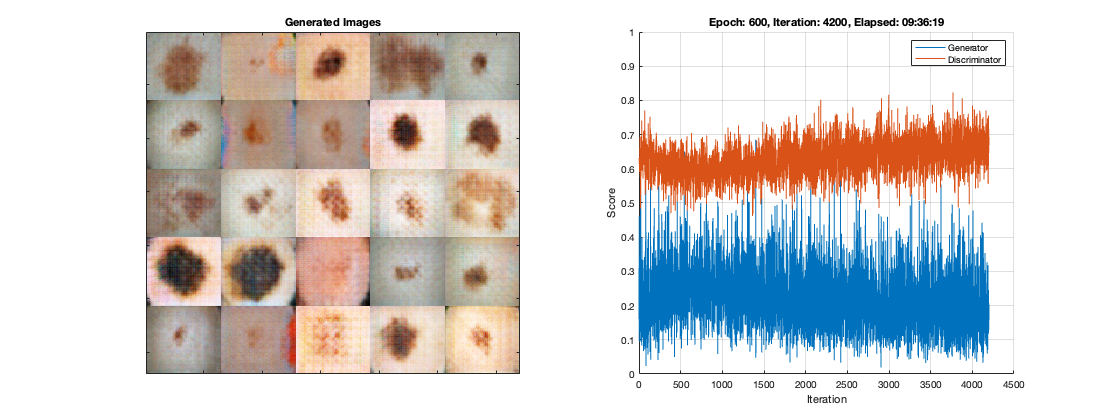

iteration = 0;
start = tic;

% Loop over epochs.
for epoch = 1:numEpochs
    
    % Reset and shuffle datastore.
    shuffle(mbq);
    
    % Loop over mini-batches.
    while hasdata(mbq)
        iteration = iteration + 1;
        
        % Read mini-batch of data.
        dlX = next(mbq);
        
        % Generate latent inputs for the generator network. Convert to
        % dlarray and specify the dimension labels 'CB' (channel, batch).
        % If training on a GPU, then convert latent inputs to gpuArray.
        Z = randn(numLatentInputs,miniBatchSize,'single');
        dlZ = dlarray(Z,'CB');        
        
        if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
            dlZ = gpuArray(dlZ);
        end
        
        % Evaluate the model gradients and the generator state using
        % dlfeval and the modelGradients function listed at the end of the
        % example.
        [gradientsGenerator, gradientsDiscriminator, stateGenerator, scoreGenerator, scoreDiscriminator] = ...
            dlfeval(@modelGradients, dlnetGenerator, dlnetDiscriminator, dlX, dlZ, flipFactor);
        dlnetGenerator.State = stateGenerator;
        
        % Update the discriminator network parameters.
        [dlnetDiscriminator,trailingAvgDiscriminator,trailingAvgSqDiscriminator] = ...
            adamupdate(dlnetDiscriminator, gradientsDiscriminator, ...
            trailingAvgDiscriminator, trailingAvgSqDiscriminator, iteration, ...
            learnRate, gradientDecayFactor, squaredGradientDecayFactor);
        
        % Update the generator network parameters.
        [dlnetGenerator,trailingAvgGenerator,trailingAvgSqGenerator] = ...
            adamupdate(dlnetGenerator, gradientsGenerator, ...
            trailingAvgGenerator, trailingAvgSqGenerator, iteration, ...
            learnRate, gradientDecayFactor, squaredGradientDecayFactor);
        
        % Every validationFrequency iterations, display batch of generated images using the
        % held-out generator input.
        if mod(iteration,validationFrequency) == 0 || iteration == 1
            % Generate images using the held-out generator input.
            dlXGeneratedValidation = predict(dlnetGenerator,dlZValidation);
            
            % Tile and rescale the images in the range [0 1].
            I = imtile(extractdata(dlXGeneratedValidation));
            I = rescale(I);
            
            % Display the images.
            subplot(1,2,1);
            image(imageAxes,I)
            xticklabels([]);
            yticklabels([]);
            title("Generated Images");
        end
        
        % Update the scores plot.
        subplot(1,2,2)
        addpoints(lineScoreGenerator,iteration,...
            double(gather(extractdata(scoreGenerator))));
        
        addpoints(lineScoreDiscriminator,iteration,...
            double(gather(extractdata(scoreDiscriminator))));
        
        % Update the title with training progress information.
        D = duration(0,0,toc(start),'Format','hh:mm:ss');
        title(...
            "Epoch: " + epoch + ", " + ...
            "Iteration: " + iteration + ", " + ...
            "Elapsed: " + string(D))
        
        drawnow
    end
end

The training plot shows the [scores](https://www.mathworks.com/help/deeplearning/ug/monitor-gan-training-progress-and-identify-common-failure-modes.html?searchHighlight=Monitor%20GAN%20Training%20Progress%20and%20Identify%20Common%20Failure%20Modes&s_tid=srchtitle) of the generator and discriminator networks over time as well as examples of synthetic images from the validation set. 

## Generate new images

To generate new images, we use the `predict` function on the generator with a `dlarray` object containing a batch of random vectors. To display the images together, we use the `imtile` function and rescale the images using the `rescale` function. 

Everytime you run this section a new set of 25 random images is displayed.

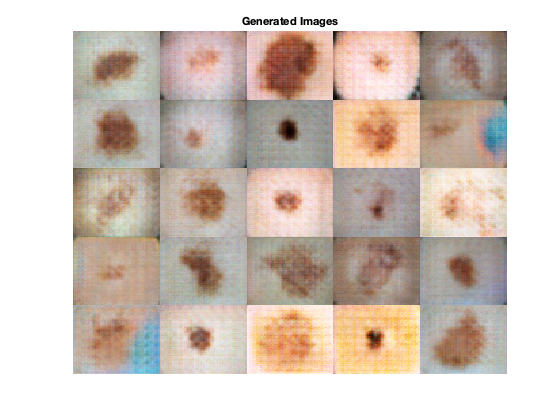

numObservations = 25;
ZNew = randn(numLatentInputs,numObservations,'single');
dlZNew = dlarray(ZNew,'CB');

if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
    dlZNew = gpuArray(dlZNew);
end

dlXGeneratedNew = predict(dlnetGenerator,dlZNew);

I = imtile(extractdata(dlXGeneratedNew));
I = rescale(I);
figure
image(I)
axis off
title("Generated Images")

## Auxiliary functions

See [https://www.mathworks.com/help/deeplearning/ug/train-conditional-generative-adversarial-network.html](https://www.mathworks.com/help/deeplearning/ug/train-conditional-generative-adversarial-network.html) for details.

function [gradientsGenerator, gradientsDiscriminator, stateGenerator, scoreGenerator, scoreDiscriminator] = ...
    modelGradients(dlnetGenerator, dlnetDiscriminator, dlX, dlZ, flipFactor)

% Calculate the predictions for real data with the discriminator network.
dlYPred = forward(dlnetDiscriminator, dlX);

% Calculate the predictions for generated data with the discriminator network.
[dlXGenerated,stateGenerator] = forward(dlnetGenerator,dlZ);
dlYPredGenerated = forward(dlnetDiscriminator, dlXGenerated);

% Convert the discriminator outputs to probabilities.
probGenerated = sigmoid(dlYPredGenerated);
probReal = sigmoid(dlYPred);

% Calculate the score of the discriminator.
scoreDiscriminator = (mean(probReal) + mean(1-probGenerated)) / 2;

% Calculate the score of the generator.
scoreGenerator = mean(probGenerated);

% Randomly flip a fraction of the labels of the real images.
numObservations = size(probReal,4);
idx = randperm(numObservations,floor(flipFactor * numObservations));

% Flip the labels.
probReal(:,:,:,idx) = 1 - probReal(:,:,:,idx);

% Calculate the GAN loss.
[lossGenerator, lossDiscriminator] = ganLoss(probReal,probGenerated);

% For each network, calculate the gradients with respect to the loss.
gradientsGenerator = dlgradient(lossGenerator, dlnetGenerator.Learnables,'RetainData',true);
gradientsDiscriminator = dlgradient(lossDiscriminator, dlnetDiscriminator.Learnables);

end

function [lossGenerator, lossDiscriminator] = ganLoss(probReal,probGenerated)

% Calculate the loss for the discriminator network.
lossDiscriminator = -mean(log(probReal)) - mean(log(1-probGenerated));

% Calculate the loss for the generator network.
lossGenerator = -mean(log(probGenerated));

end

function X = preprocessMiniBatch(data)

% Concatenate mini-batch
X = cat(4,data{:});

% Rescale the images in the range [-1 1].
X = rescale(X,-1,1,'InputMin',0,'InputMax',255);

end